Metemos las plantas del controlador y del sistema:


C_s_num = [0.525,5.022,4.4]

C_s_num =     0.5250    5.0220    4.4000


C_s_den = [0.005,1,0]

C_s_den =     0.0050    1.0000         0


Numerador y denominador


C_s= tf (C_s_num,C_s_den)

C_s =
 
  0.525 s^2 + 5.022 s + 4.4
  -------------------------
        0.005 s^2 + s
 
Continuous-time transfer function.




G_s_num= [52.1]

G_s_num = 52.1000

G_s_den = [1.21,1,0]

G_s_den =     1.2100    1.0000         0



G_s= tf (G_s_num,G_s_den)

G_s =
 
      52.1
  ------------
  1.21 s^2 + s
 
Continuous-time transfer function.



Función para convertir la posción de los polos 

Ahora vamos a obtener la función en lazo cerrado. Usar los siguientes comandos


C_s.InputName = 'e'; C_s.OutputName = 'u';
G_s.InputName = 'u'; G_s.OutputName = 'y';

sum = sumblk('e','r','y','+-');
controlled = connect(G_s,C_s,sum, 'r','y');


Otra opcion es usar la función **feedback asi:**

M= feedback (C_s*G_s,1)

M =
 
  From input "u" to output "u":
                                     
          27.35 s^2 + 261.6 s + 229.2
                                     
  -------------------------------------------
                                             
  0.00605 s^4 + 1.215 s^3 + 28.35 s^2        
                                             
                            + 261.6 s + 229.2
                                             
 
Continuous-time transfer function.



Ahora analizaremos las TF con las funciones de Control Toolbox de Matlab y analizamos las caracteristicas secuenciales

Analisis de C_s:

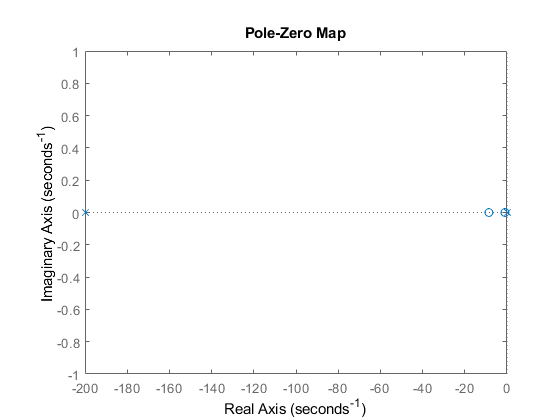

pzmap(C_s) %colocación de polos y ceros en grafica compleja

pole(C_s) %resolución de polos de la TF dada

ans =      0
  -200


zero(C_s) %Raices del numerador de la TF dada

ans =    -8.5901
   -0.9757


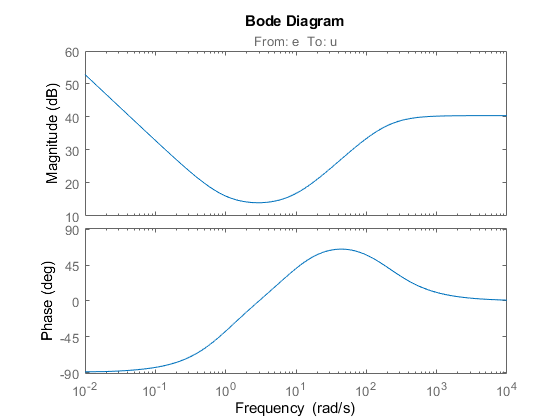

bode(C_s)

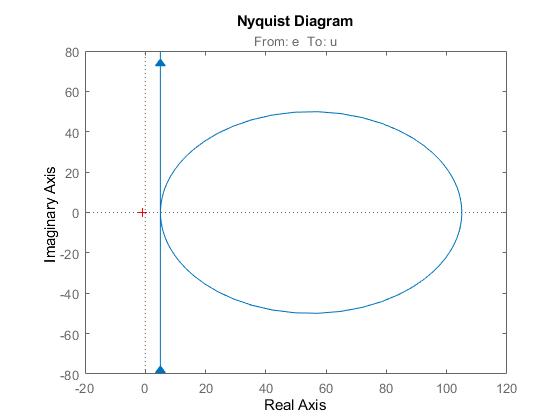

nyquist (C_s)

Analisis de G_s:

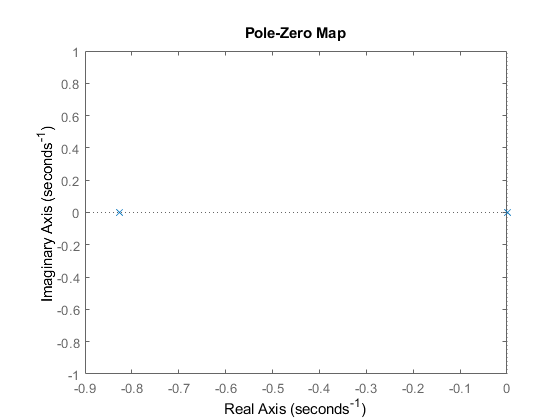

pzmap(G_s) %colocación de polos y ceros en grafica compleja

pole(G_s) %resolución de polos de la TF dada

ans =          0
   -0.8264


zero(G_s) % Raices del numerador de la TF dada


ans =

  0×1 empty double column vector



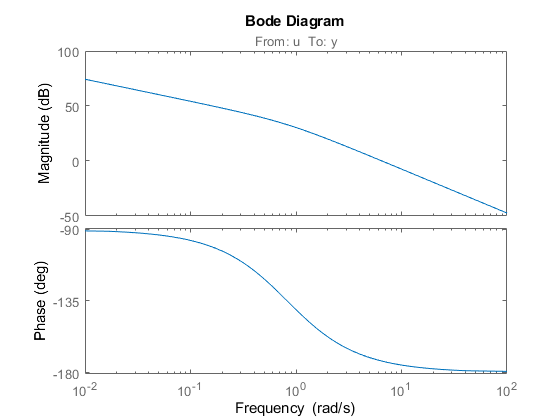

bode(G_s)

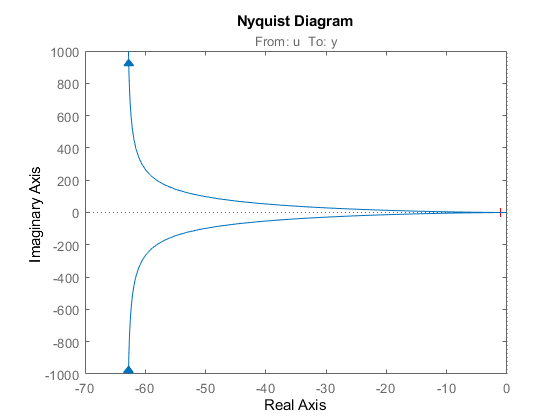

nyquist (G_s)

Ahora vamos a hacer la discretización de Tustin(bilineal) con 2 periodos diferentes, para ello hay que calcular el ancho de banda del sistema controlado en lazo cerrado. 

podemos usar la funcion margins de matlab para ver el ancho de banda del sistema en lazo cerrado.

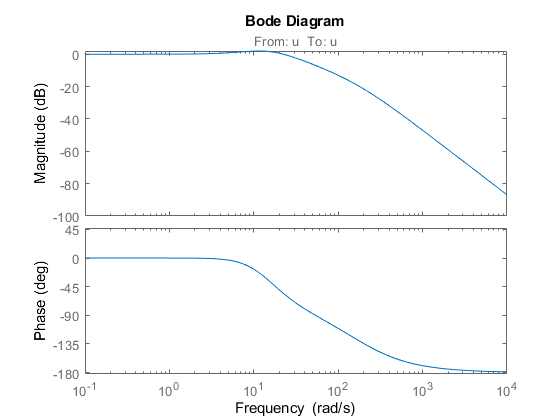

bode(M)

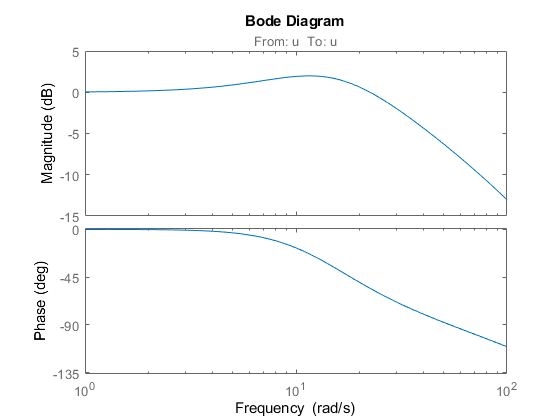

%Asi limitamos el orden de la potencia de 10 y el numero de puntos (1000)
%que poner
bode(M, logspace(0,2,1000))

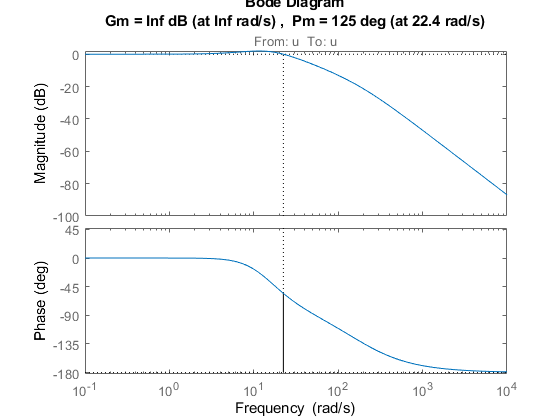

margin(M) % Margen de fase y ganancia.


bandwidth(M) %Ans = 34.1359 de locos

ans = 34.1359

Siguiendo las indicaciones del documento elegimos las siguientes Ts

Ts1= 1/(10*34.1359)

Ts1 = 0.0029

Ts2= 1/(100*34.1359)

Ts2 = 2.9295e-04

Ahora podemos discretizar el controlador con los dos periodos diferentes:

C_z1=c2d(C_s,Ts1,'tustin')

C_z1 =
 
  From input "e" to output "u":
  82.35 z^2 - 162.4 z + 80.07
  ---------------------------
    z^2 - 1.547 z + 0.5469
 
Sample time: 0.0029295 seconds
Discrete-time transfer function.



C_z2=c2d(C_s,Ts2,'zoh')

C_z2 =
 
  From input "e" to output "u":
  105 z^2 - 209.7 z + 104.7
  -------------------------
   z^2 - 1.943 z + 0.9431
 
Sample time: 0.00029295 seconds
Discrete-time transfer function.




C_z1.InputName = 'e1'; C_z1.OutputName = 'u1';
C_z2.InputName = 'e2'; C_z2.OutputName = 'u2';

Analisis de los sistemas discretizados:

Con el primer periodo de muestreo:

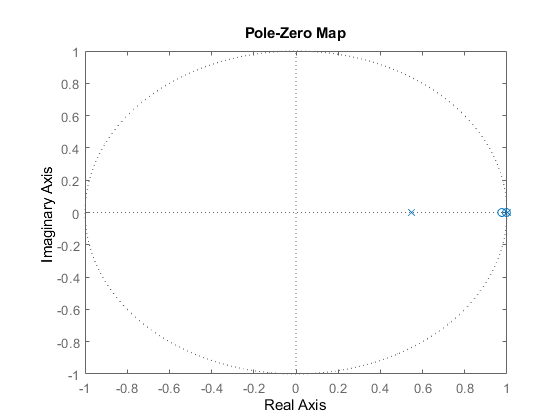

pzmap(C_z1)

Con el segundo periodo de muestreo:

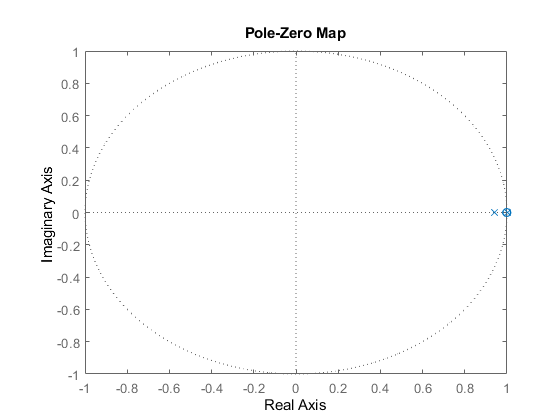

pzmap(C_z2)

aparte del analisis de ubicación de polos y ceros vamos a analizar el cambio de margen de fase y ganancia en lazo abierto con los nuevos controladores. Para ello haremos lo siguente:

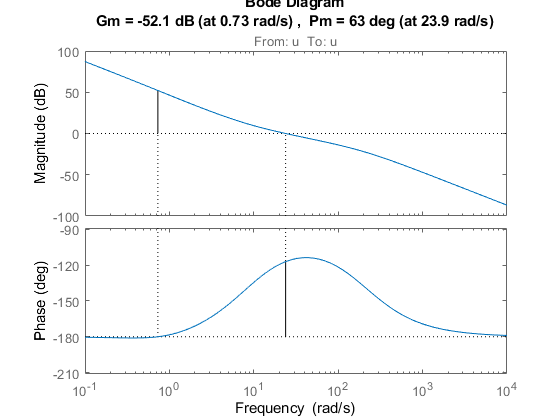

margin(C_s*G_s)

allmargin(C_s*G_s)

ans = struct with fields:
     GainMargin: [0 0.0025 Inf]
    GMFrequency: [0 0.7303 Inf]
    PhaseMargin: 63.0401
    PMFrequency: 23.8620
    DelayMargin: 0.0461
    DMFrequency: 23.8620
         Stable: 1


Reconstruyendo el controlador 1:

C_s_r1 = d2c(C_z1,'tustin')

C_s_r1 =
 
  From input "e1" to output "u1":
  105 s^2 + 1004 s + 880
  ----------------------
  s^2 + 200 s + 7.58e-12
 
Continuous-time transfer function.



C_s_r1.InputName = 'e1'; C_s_r1.OutputName = 'u1';

Entonces el sistema en lazo abierto:

sys_la1 = C_s_r1*G_s

sys_la1 =
 
  From input "u" to output "u1":
      5470 s^2 + 5.233e04 s + 4.585e04
  -----------------------------------------
  1.21 s^4 + 243 s^3 + 200 s^2 + 7.58e-12 s
 
Continuous-time transfer function.



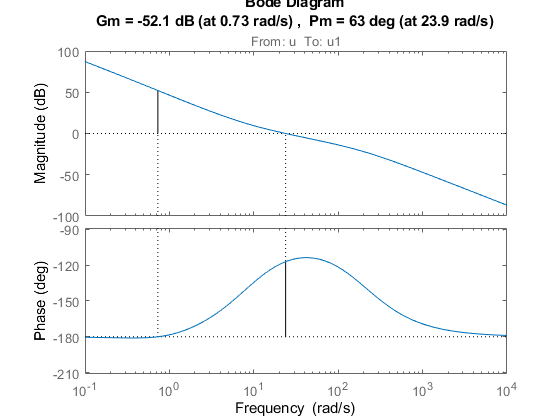

margin(sys_la1)

allmargin(sys_la1)

ans = struct with fields:
     GainMargin: [2.2451e-15 0.0025 Inf]
    GMFrequency: [7.1740e-07 0.7301 Inf]
    PhaseMargin: 63.0401
    PMFrequency: 23.8620
    DelayMargin: 0.0461
    DMFrequency: 23.8620
         Stable: 1


Reconstruyendo el controlador 1:


C_s_r2 = d2c(C_z2,'tustin')

C_s_r2 =
 
  From input "e2" to output "u2":
  107.9 s^2 + 1004 s + 879.7
  --------------------------
  s^2 + 199.9 s + 3.031e-10
 
Continuous-time transfer function.



C_s_r2_zoh= d2c(C_z2,'zoh')

C_s_r2_zoh =
 
  From input "e2" to output "u2":
  105 s^2 + 1004 s + 880
  -----------------------
  s^2 + 200 s + 1.364e-09
 
Continuous-time transfer function.



t=0:Ts2:0.1

t =          0    0.0003    0.0006    0.0009    0.0012    0.0015    0.0018    0.0021    0.0023    0.0026    0.0029    0.0032    0.0035    0.0038    0.0041    0.0044    0.0047    0.0050    0.0053    0.0056    0.0059    0.0062    0.0064    0.0067    0.0070    0.0073    0.0076    0.0079    0.0082    0.0085    0.0088    0.0091    0.0094    0.0097    0.0100    0.0103    0.0105    0.0108    0.0111    0.0114    0.0117    0.0120    0.0123    0.0126    0.0129    0.0132    0.0135    0.0138    0.0141    0.0144



U=ones(size(t))

U =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


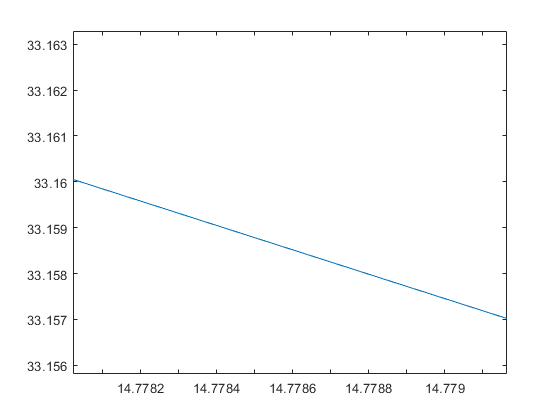

%[Y,Tsim,X] = step(C_s_r2_zoh,U,t)

plot(step(C_s_r2_zoh))


%plot(C_s_r2_zoh)
C_s_r2.InputName = 'e1'; C_s_r1.OutputName = 'u1';
sys_la2 = C_s_r2*G_s

sys_la2 =
 
  From input "u" to output "u2":
                                       
       5623 s^2 + 5.231e04 s + 4.583e04
                                       
  -------------------------------------------
                                             
  1.21 s^4 + 242.9 s^3 + 199.9 s^2           
                                             
                                + 3.031e-10 s
                                             
 
Continuous-time transfer function.



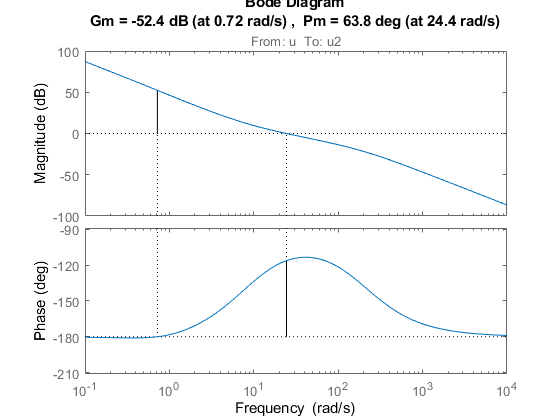

margin(sys_la2)

allmargin(sys_la2)

ans = struct with fields:
     GainMargin: [8.9626e-14 0.0024 Inf]
    GMFrequency: [4.5327e-06 0.7204 Inf]
    PhaseMargin: 63.8417
    PMFrequency: 24.3841
    DelayMargin: 0.0457
    DMFrequency: 24.3841
         Stable: 1
